# Train DQN Agent for Haptic Shared Control

This project shows how to train a Deep Q-Learning Network (DQN) agent for haptic shared control in Simulink. 

clear all;
addpath(genpath(pwd));

## Simulink Model for Ego Car

The reinforcement learning environment for this project is a simple bicycle model for ego vehicle dynamics. The training goal is to keep the ego vehicle traveling along the centerline of the lanes by providing haptic guidance torque on the steering wheel. 

% Driver-vehicle-road system parameters setting
run SimModel_R2019a_RL_Para;
H_K2  = 1.0;
D_Kw  = 4.0*1.00;
D_KHG = -1.0*0.0; 
D_Td   = 0.1000;
Band_TH = 0.0;

Define the simulation duration, tf, and sample time, dt,  in seconds.

tf = 60*2;      % simulation time (s):60*10 (default)
dt = 1/60*10;   % simulation rate (s):1/60  (default)

Define the disturbance.

% Disturbance setting
Randperm_Disturbance = randperm(1); % Random_Disturbance (20)
Random_Disturbance = 20*2+ Randperm_Disturbance(1,1); % Random_Disturbance

Fix the random generator seed for reproducibility.

rng(0);

The output of the shared control system is the front steering angle of the ego car. Considering the physical limitations of the ego car, the steering angle is constrained to the range [-0.5,0.5] rad.

% u_min = -0.5;
% u_max = 0.5;

Open the model.

mdl = 'SimModel_R2019a_RL';
open_system(mdl);
agentblk = [mdl '/Subsystem/Haptic Guiance Model/RL Agent'];

For this model:

- The action signal from the agent to the environment is the gain of haptic guidance, 0.0, 0.1,..., 0.9, 1.0.

- The observations from the environment are the lateral error, steering wheel angle, and their derivatives.

- The simulation is terminated when lateral error > 0.1.

- The reward r, provided at every time step $t$, is:

r = 0.1 - |*SWA*|

## Create Environment Interface

Create a reinforcement learning environment interface for the ego vehicle. To do so, first create the observation and action specifications.

% create observation info
observationInfo = rlNumericSpec([4 1],'LowerLimit',-inf*ones(4,1),'UpperLimit',inf*ones(4,1));
observationInfo.Name = 'observations';
observationInfo.Description = 'information on lateral deviation and relative yaw angle';
% create action Info
actionInfo = rlFiniteSetSpec((0:10)*0.1);
actionInfo.Name = 'steering';
% define environment
env = rlSimulinkEnv(mdl,agentblk,observationInfo,actionInfo);

The interface has a discrete action space where the agent can apply one of 11 possible haptic guidance gain from 0.0 to 1.0.

## Create DQN agent

A DQN agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

L = 24; % number of neurons
statePath = [
    imageInputLayer([4 1 1], 'Normalization', 'none', 'Name', 'state')
    fullyConnectedLayer(L, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(L, 'Name', 'fc2')
    additionLayer(2,'Name','add')
    reluLayer('Name','relu2')
    fullyConnectedLayer(L, 'Name', 'fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(1, 'Name', 'fc4')];

actionPath = [
    imageInputLayer([1 1 1], 'Normalization', 'none', 'Name', 'action')
    fullyConnectedLayer(L, 'Name', 'fc5')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);    
criticNetwork = connectLayers(criticNetwork,'fc5','add/in2');

View the critic network configuration.

% figure
% plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4); % 'LearnRate',1e-3

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation information for the critic, which you obtain from the environment interface. For more information, see [`rlRepresentation`](docid:rl_ref#mw_453a7f45-3761-4387-9e1d-4c90ed8b5b57).

critic = rlRepresentation(criticNetwork,criticOptions,'Observation',{'state'},observationInfo,'Action',{'action'},actionInfo);

To create the DQN agent, first specify the DQN agent options using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e).

agentOptions = rlDQNAgentOptions(...
    'SampleTime',dt,...
    'UseDoubleDQN',true,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.99,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',64);

Then, create the DQN agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 5000 episodes, with each episode lasting at most 720 time steps.

- Display the training progress in the Episode Manager dialog box.

- Stop training when the episode reward reaches 

- `2*60/dt*((0.1-0.010)+(0)))`. 

- Save a copy of the agent for each episode where the cumulative reward is greater than 

- `2*60/dt*((0.1-0.030)+(0)))`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(tf/dt);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue', 2*60/dt*((0.1-0.010)+(0)),...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue', 2*60/dt*((0.1-0.030)+(0)));

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

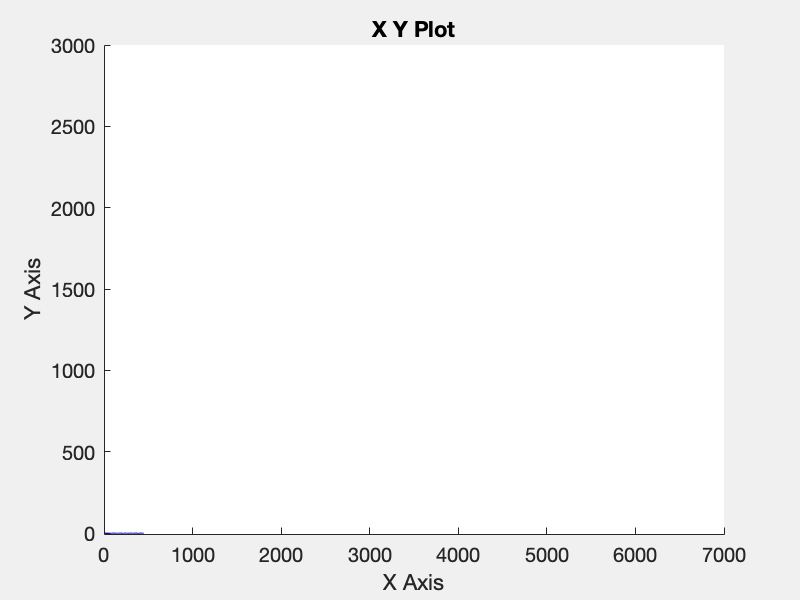

doTraining = true;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOpts);
else
    % Load pretrained agent for the example.
    load('Agent0.mat','saved_agent')  
    agent = saved_agent;
end

## Simulate DQN Agent

To validate the performance of the trained agent, uncomment the following two lines and simulate it within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

% simOptions = rlSimulationOptions('MaxSteps',maxsteps);
% experience = sim(env,agent,simOptions);

To demonstrate the trained agent on deterministic initial conditions, simulate the model in Simulink. 

Simout_RL = sim(mdl);

Close the Simulink model. 

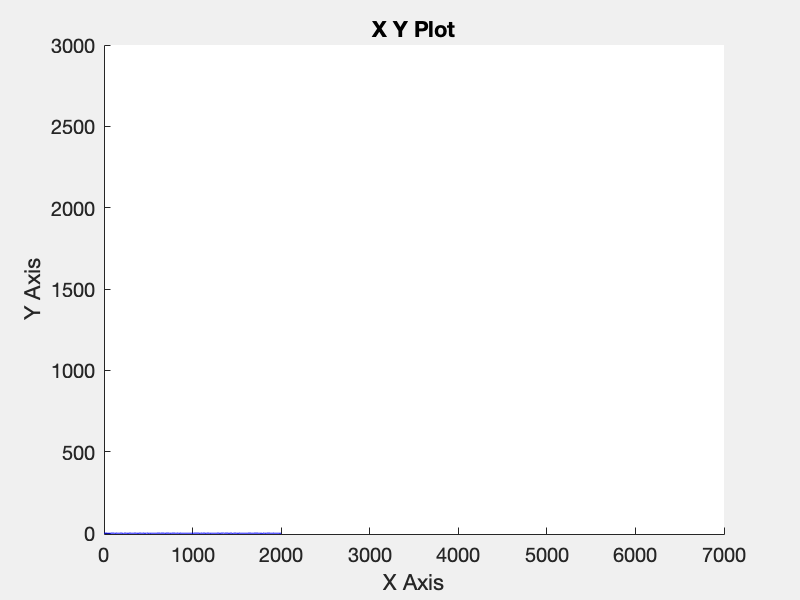

% bdclose(mdl);

*Copyright 2019 WANG Zheng, K. Nakano Lab., The University of Tokyo.*